# Supplementary figure 1: How to construct spatial dependent plasticity function

### Fig A: fit $f_P$ and $f_D$ for different velocities

Manuel fit the parameter of potentiation and depotentiation function to the biophysical model

exp: 9-6

clear; clc
L = 187;        init_weight = 0;        n_ca3 = 100;
inductions = [1, L/2];

velocity = 20;
%velocity = 35;
[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3);

i = 1;
pot_r = list_pot(i, :);
pot_m = list_pot_map(i, :);
dep_r = list_dep(i, :);
dep_m = list_dep_map(i, :);

ind_pos = inductions(inductions(:, 1) == 1, 2);
phase_map = ca3_peak_locations_map / L * 2*pi;
phase = ca3_peak_locations /  L * 2*pi;
phase_ind = ind_pos /  L * 2*pi;  
figure
plot(phase, pot_r, ".k" , "MarkerSize", 30)
hold on
plot(phase_map, pot_m, "-r", "LineWidth", 4.5)
xline(phase_ind, "--k", "LineWidth", 4.5)
if velocity == 20
legend({"Biophysical", "P\cdotf_P"}, 'location', 'northeast')
legend boxoff
hold off
end
box off
ylim([0, 0.8])
yticks([0, 0.2, 0.4, 0.6, 0.8])
yticklabels([0, "", "", "", 0.8])
xlim([0, 2*pi])
xticks([0, pi, 2*pi])
xticklabels([0, " ", "2\pi"])
fig_config(80)

figure
plot(phase, dep_r, ".k" , "MarkerSize", 30)
hold on
plot(phase_map, dep_m, "-b", "LineWidth", 4.5)
xline(phase_ind, "--k", "LineWidth", 4.5)
if velocity == 20
legend({"Biophysical", "P\cdotf_D"}, 'location', 'northeast')
legend boxoff
end
hold off
box off
ylim([0, 0.8])
yticks([0, 0.2, 0.4, 0.6, 0.8])
yticklabels([0, "", "", "", 0.8])
xlim([0, 2*pi])
xticks([0, pi, 2*pi])
xticklabels([0, " ", "2\pi"])
fig_config(80)

### Figure B-C: Simulations using different induction protocols shouw 1D map can match the results of biophysical model

Repetitive induction on same position 5 times

exp 9-6

clear; clc
L = 187;        init_weight = 0;        n_ca3 = 100;
inductions = [[1:5]' ones(5, 1) * L /2];
velocity = 25;
[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3);

figure
lap_1 = inductions(1, 1);
ind_1 = inductions(1, 2);
weight_R = synaptic_weight(lap_1 + 1, :);
weight_M = synaptic_weight_map(lap_1 + 1, :);
plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 40)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
hold off
xline(ind_1, "--", "LineWidth", 4.5)
xlim([0, L])
legend boxoff
xticks([0, 187/4, 187/2, 187*3/4, 187])
xticklabels(["0", "", "", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
legend({"Biophysical", "Map"})
fig_config(90)


% second
lap_2 = inductions(5, 1);
ind_2 = inductions(5, 2);
weight_R = synaptic_weight(lap_2 + 1, :);
weight_M = synaptic_weight_map(lap_2 + 1, :);

plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 40)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
xline(ind_2, "--", "LineWidth", 4.5)
hold off
xlim([0, L])
xticks([0, 187/4, 187/2, 187*3/4, 187])
xticklabels(["0", "", "", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
fig_config(90)

Double induction in a single lap.

inductions = [1, 30; 1, 120; 2, L/ 2];

[synaptic_weight_map, list_pot_map, list_dep_map, ca3_peak_locations_map] = Sim_CA3CA1_map(velocity, inductions, init_weight, L, n_ca3);
[synaptic_weight, list_pot, list_dep, ca3_peak_locations] = Sim_CA3CA1_Romani(velocity, inductions, init_weight, L, n_ca3);

lap_1 = inductions(1, 1);
ind_1 = inductions(1, 2);
ind_2 = inductions(2, 2);
weight_R = synaptic_weight(lap_1 + 1, :);
weight_M = synaptic_weight_map(lap_1 + 1, :);
plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 40)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
hold off
xline(ind_1, "--", "LineWidth", 4.5)
xline(ind_2, "--", "LineWidth", 4.5)
xlim([0, L])
%legend boxoff
xticks([0, 187/4, 187/2, 187*3/4, 187])
xticklabels(["0", "", "", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
%legend({"Biophysical", "Map", "Plateau"})
fig_config(90)

% second
lap_2 = inductions(3, 1);
ind_2 = inductions(3, 2);
weight_R = synaptic_weight(lap_2 + 1, :);
weight_M = synaptic_weight_map(lap_2 + 1, :);

plot(ca3_peak_locations, weight_R, ".k", "MarkerSize", 40)
hold on
box off
plot(ca3_peak_locations_map, weight_M, "-k", "LineWidth", 4.5)
xline(ind_2, "--", "LineWidth", 4.5)
hold off
xlim([0, L])
xticks([0, 187/4, 187/2, 187*3/4, 187])
xticklabels(["0", "", "", "", "2\pi"])
ylim([0, 1])
yticks([0, 0.5, 1])
yticklabels([0, "", 1])
fig_config(90)

## Fig D-E: comparison of weight change heatmap for different parameter sets.

### D: $V= 35cm/s, L = 187 cm$

Bio: $\tau_{Elig} = 0.98, \tau_{IS} = 0.64, \alpha_{+} = 0.19, \beta_{+}= 23.82, \alpha{-} = 0.05, \beta_{-} = 730.64,  k_{+} = 0.8, k_{-} = 0.44$ 

Map: $\nu_P = 6, \mu_P = 0.95, \sigma_P= 1.45, \lambda_P = -4.5, P = 2, \nu_D = 5, \mu_D = 1.6, \sigma_D= 2.5, \lambda_D = -6, D = 2.65$

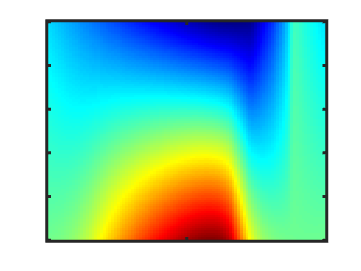

clear; clc;
load(fullfile(read_output_dir(), "SupFig1/Bio_Plasticity.mat"))
param_P = [6, 0.95, 1.45, -4.5];
param_D = [5, 1.6, 2.5, -6];
P = 2; D = 2.65;
[f_P, f_D] = pot_dep_func(L, velocity, param_P, param_D);

relative_time = (ca3_peak_locations - L/2) / velocity;
phase = (ca3_peak_locations - L/2) / L * 2 * pi;

pot_map = P * f_P(relative_time);
dep_map = D * f_D(relative_time);

[dw_bio, init_weights] = update_weight(pot_bio_1, dep_bio_1);
dw_map = update_weight(pot_map, dep_map);

v_m = max(max((dw_bio(:))), max((dw_map(:))));
v_min = min(min((dw_bio(:))), min((dw_map(:))));
plot_heatmap(phase, init_weights, dw_bio, v_m, v_min)

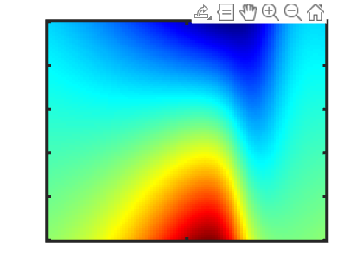


plot_heatmap(phase, init_weights, dw_map, v_m, v_min)

### E: $V= 35cm/s, L = 187 cm$

Bio: $\tau_{Elig} = 0.8, \tau_{IS} = 0.5, \alpha_{+} = 0.2, \beta_{+}= 30, \alpha{-} = 0.1, \beta_{-} = 1000,  k_{+} = 0.8, k_{-} = 0.4$ 

Map: $\nu_P = 5, \mu_P = 0.8, \sigma_P= 1.35, \lambda_P = -6, P = 1.6, \nu_D = 5, \mu_D = 1.1, \sigma_D= 1.7, \lambda_D = -7, D = 1.2$

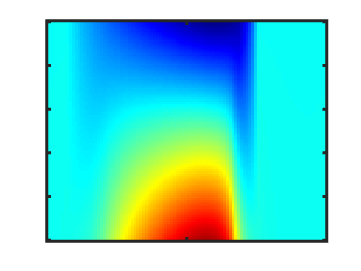

param_P = [5, 0.8, 1.35, -6];
param_D = [5, 1.1, 1.7, -7];
P = 1.6; D = 1.2;
[f_P, f_D] = pot_dep_func(L, velocity, param_P, param_D);

pot_map = P * f_P(relative_time);
dep_map = D * f_D(relative_time);

[dw_bio, init_weights] = update_weight(pot_bio_2, dep_bio_2);
dw_map = update_weight(pot_map, dep_map);

v_m = max(max((dw_bio(:))), max((dw_map(:))));
v_min = min(min((dw_bio(:))), min((dw_map(:))));
plot_heatmap(phase, init_weights, dw_bio, v_m, v_min)

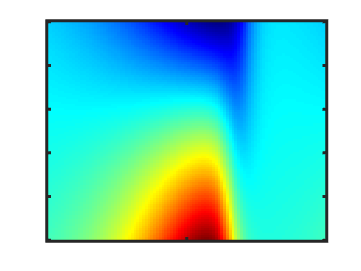


plot_heatmap(phase, init_weights, dw_map, v_m, v_min)

function [f_P, f_D] = pot_dep_func(L, velocity, param_P, param_D)
%{
Define the underlying bioprocesses using skewed t student function  
https://ieeexplore.ieee.org/document/7217164
%}
   
    if nargin < 3
        % parameter are nu, mu, sigma, skew
        % nu: degree of t student
        % mu: location
        % sigma: scale
        % negative skew control the movement of the center toward right
        %{
        tag_999: dont modify these parameters
        param_P = ; 
        param_D = ; 
        %}
        % tag_1000 current parameter 08/10/2022
        if velocity == 25
            param_P = [3.5, 0.685, 1.65, -1.61]; 
            param_D = [5, 1.75, 3.65, -5.35]; 
        elseif velocity == 15
            param_P = [5, 0.75, 1.97, -1.375]; 
            param_D = [3, 2.15, 3.15, -3.5];             
        elseif velocity == 35
            param_P = [2, 0.6, 1.42, -1.625]; 
            param_D = [3, 1.54, 3.85, -5.75]; 
        else %if velocity == 20
            param_P = [5, 0.75, 1.825, -1.55]; 
            param_D = [5, 1.875, 3.45, -4.55]; 
        end
    end
    
    f_P = plasticity(param_P(1), param_P(2), param_P(3), param_P(4));
    f_D = plasticity(param_D(1), param_D(2), param_D(3), param_D(4));
    
    function f = plasticity(nu, mu, sigma, skew)
            
            f = @(x) 0;
            k_max = 10;
            for k = -1*k_max  : k_max
                f = @(x) f(x) + 2/sigma .* tpdf((x + L / velocity *k - mu)/sigma, nu) .* ...
                    tcdf(skew * (x + L / velocity *k - mu)/sigma .* ...
                    sqrt( (nu+1)./(nu+ (x + L / velocity *k - mu).^2/sigma^2) ), nu + 1);
            end
    end
end


function [dw, init_weights] = update_weight(potentiation, depression)
    init_weights = 0:0.01:1;
    init_weights = init_weights';
    current_weight = init_weights;
    

    for i = 1:1
        dwdt = potentiation .* (1 - current_weight) - depression .* current_weight;
        current_weight = current_weight  + dwdt;
        current_weight = max(0, min(1, current_weight));
    end


    dw = current_weight - init_weights;
end


function plot_heatmap(x, y , data, v_m, v_min)
    imagesc(x, y, data)
    xlim([-pi, pi])
    xticks([-pi, 0, pi])
    xticklabels([""])
    yticks(0.2 * (0:5))
    yticklabels([""])
    colormap(jet)
    set(gca,'YDir','normal')
     ax = gca;
    ax.LineWidth = 2;
    caxis([v_min, v_m])
end